# Single-antenna Basestation

clc
close all
addpath('C:\Users\Asus irG\Documents\Github\RIS-Sharing-Scenario\common methods') % You need to change the address in case you run it on your computer

%% parameters
N1 = 3 ;                           % No.  users
N_i = 32 ;                         % No.  IRS elements
N_iter = 1000 ;                     % No. iteraions
P_T = (10^(40/10)) * 1e-3 ;               % BS power(w)
R = 10 ;                           % Radius
[x0 , y0 , z0] = deal(30 , 20 , 0) ;         % user area center
[x1 , y1 , z1] = deal(0 , 0 , 10) ;       % BS1 location
[x_i , y_i , z_i] = deal(25 * sqrt(2) , 25 * sqrt(2) , 10) ;   % IRS location
M_t = 1 ;                          % No. of transmitter antennas
M_r = 1 ;                          % No. of receiver antennas
alpha_d = 3.6 ;
alpha_r = 2 ;
noise_power = (10^(-114/10)) ;     % -169dbm/Hz
interference = 0 ;
epsilon = 0.01 ;
SV = 21 ;

%% users location
t = 2 * pi * rand(N1 , 1) ;
r  =  R * sqrt(rand(N1 , 1)) ;
x  =  x0 + r.* cos(t) ;
y  =  y0 + r.* sin(t) ;
z = 1.5 * ones(N1 , 1) ;

## Rate vs No. RIS elements

%%  
channel_gain = zeros(N1 , 1) ;
final_Lband = zeros(SV+1  ,  1) ;
final_Uband = zeros(SV+1  ,  1) ;
final_rate = zeros(SV +1 , 1) ;
random_final_rate = zeros(SV + 1 , 1) ;
tic
start = 10 ;
step = 5 ;
m = repmat('.' ,  1 ,  SV) ;
for N = start : step : start + (SV - 1) * step
    i = (N - start)/step + 1 ;
    m(i) = '|' ;
    disp(m)
    for k = 1 : N_iter
        t = 2 * pi * rand(N1 , 1) ;
        r  =  R * sqrt(rand(N1 , 1)) ;
        x  =  x0 + r.* cos(t) ;
        y  =  y0 + r.* sin(t) ;
        %% channel gains
        h_d = (10^0.2) * (randn(N1 , M_t , M_r) + 1j * randn(N1 , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x-x1).^2 + (y-y1).^2 + (z-z1).^2 )).^alpha_d) ;
        g = (10^0.2) * (randn(N , M_t , M_r) + 1j * randn(N , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x_i-x1).^2 + (y_i-y1).^2 + (z_i-z1).^2 )).^alpha_r) ;
        h_r = zeros(N , N1) ;
        for j = 1 : N1
            h_r( :  , j) = (10^0.2) * (randn(N , M_t , M_r) + 1j * randn(N , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x(j)-x_i).^2 + (y(j)-y_i).^2 + (z(j)-z_i).^2 )).^alpha_r) ;
        end
       
        %% channel gains
        [exact_rate ,  Z_cvx1] = Rate2(h_d ,  g ,  h_r ,  N1 ,  N ,  P_T ,  noise_power ,  N_iter) ;
        Theta = diag(Z_cvx1) ;
        channel_gain = sort(abs(h_d + h_r'  *  Theta  *  g)) ;
%         [exact_rate ,  ~] = SISONoma(epsilon ,  channel_gain1.^2  *  P_T / noise_power) ;
        final_rate(i + 1) = final_rate(i + 1) +  exact_rate ;
        rate_lower_bound = log2(1 + P_T * channel_gain(1)^2/noise_power)/N1 ;
        final_Lband(i + 1) = final_Lband(i + 1) +  rate_lower_bound ;

        rate_upper_bound = log2(1 + P_T * channel_gain(end)^2/noise_power)/N1 ;
        final_Uband(i + 1) = final_Uband(i + 1) +  rate_upper_bound ;

        %% random theta
        rand_theta = exp(1j * 2 * pi * rand(N , 1))  ;
        channel_gain = abs(h_d + h_r' * diag(rand_theta) * g)  ;
        channel_gain = sort(abs(channel_gain))  ;
        rate_lower_bound = log2(1 + P_T * channel_gain(1)^2/noise_power)/N1 ;
        random_final_rate(i + 1) = random_final_rate(i + 1) + rate_lower_bound ;
    end
end
    %% without IRS
% for k = 1 : N_iter
%     h_d = sort(abs(h_d)) ;
%     rate_lower_bound = log2(1 + P_T * h_d(1)^2/noise_power)/N1 ;
%     final_Lband(1) = final_Lband(1) +  rate_lower_bound ;
%     [exact_rate ,  ~] = SISONoma(epsilon ,  h_d.^2  *  P_T / noise_power) ;
%     final_rate(1) = final_rate(1) + exact_rate ;          
% end
final_rate = final_rate/N_iter ;
final_Lband = final_Lband/N_iter ;
final_Uband = final_Uband/N_iter ;
random_final_rate = random_final_rate/N_iter ;
toc

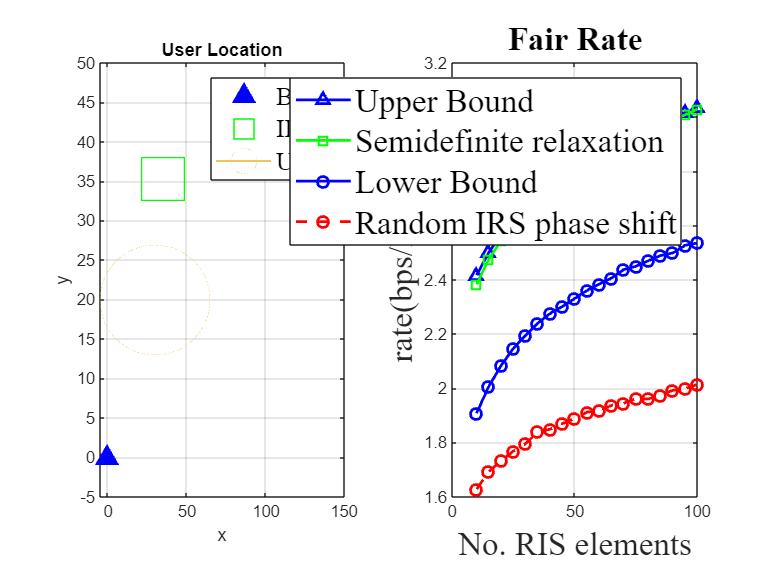

%% plot 1 Rate
figure
tiledlayout(1 , 2)
nexttile
%  draw BS1
set(gca , 'FontName' , 'Times New Roman' , 'FontSize' , 11 , 'LineWidth' , 1.5)  ; 
plot(0 , 0 , '^' , 'MarkerSize' , 10 , ...
    'MarkerEdgeColor' , 'b' , ...
    'MarkerFaceColor' , 'b' , 'linewidth' , 1)
hold on
% draw IRS
plot(x_i , y_i , 'gs' , 'MarkerSize' , 30 , 'linewidth' , 1)
% draw BS1 users
plot(x0 , y0 , 'o-' , 'MarkerSize' , 60  *  R/10 , 'linewidth' , 0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150])  ; 
ylim([-5 50])  ; 
lgnd = legend('BS1' , 'IRS' , 'UE1')  ;
set(lgnd,'FontSize',14);
set(lgnd,'FontName','Times New Roman');
grid on
nexttile
% draw results
plot([start : step : start + (SV - 1) * step] , final_Uband ,  'b-^' , 'linewidth' , 1.5)
hold on
plot([ start : step : start + (SV - 1) * step] , final_rate ,  'g-s' , 'linewidth' , 1.5)
plot([start : step : start + (SV - 1) * step] , final_Lband ,  'b-o' , 'linewidth' , 1.5)
plot([ start : step : start + (SV - 1) * step] , random_final_rate ,  'r--o' , 'linewidth' , 1.5)
set(gcf , 'color' , 'w');
% ylim([0 6])
title('Fair Rate', 'FontName','Times New Roman', 'FontSize',18)
xlabel('No. RIS elements', 'FontName','Times New Roman', 'FontSize',18)
ylabel('rate(bps/Hz)', 'FontName','Times New Roman', 'FontSize',18)
% lgnd = legend('Upper Bound','SDR' ,  'Lower Bound'   , 'Random');
lgnd = legend('Upper Bound','Semidefinite relaxation' ,  'Lower Bound'   , 'Random IRS phase shift');
set(lgnd,'FontSize',18);
set(lgnd,'FontName','Times New Roman');
grid on

% saveas(gcf , ['rate for ' ,  num2str(N_iter) , ' Iterations and ' ,  num2str(N1) , ' users.epsc'])

## SumRate vs No. users

The effect of number od users onsum-rate

%%  
channel_gain = zeros(N1 , 1) ;
final_Uband = zeros(SV  ,  1) ;
final_Lband = zeros(SV  ,  1) ;
final_rate = zeros(SV , 1) ;
random_final_rate = zeros(SV , 1) ;
start = 3 ;
step = 1 ;
tic
for N1 = start : step : start + (SV - 1) * step
    %% users location
    t = 2 * pi * rand(N1 , 1) ;
    r  =  R * sqrt(rand(N1 , 1)) ;
    x  =  x0 + r.* cos(t) ;
    y  =  y0 + r.* sin(t) ;
    z = 1.5 * ones(N1 , 1) ;
    N = N_i ;
    m = repmat('.' ,  1 ,  SV) ;
    i = (N1 - start)/step + 1 ;
    m(i) = '|' ;
    disp(m)
    for k = 1 : N_iter
        %% channel gains
        h_d = (10^0.2) * (randn(N1 , M_t , M_r) + 1j * ...
            randn(N1 , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./...
            (sqrt( (x-x1).^2 + (y-y1).^2 + (z-z1).^2 )).^alpha_d) ;
        g = (10^0.2) * (randn(N , M_t , M_r) + 1j * randn(N , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x_i-x1).^2 + (y_i-y1).^2 + (z_i-z1).^2 )).^alpha_r) ;
        h_r = zeros(N , N1) ;
        for j = 1 : N1
            h_r( :  , j) = (10^0.2) * (randn(N , M_t , M_r) + 1j * randn(N , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x(j)-x_i).^2 + (y(j)-y_i).^2 + (z(j)-z_i).^2 )).^alpha_r) ;
        end
        %% channel gains
        [exact_rate ,  Z_cvx1] = Rate2(h_d ,  g ,  h_r ,  N1 ,  N ,  P_T ,  noise_power ,  N_iter) ;
        Theta = diag(Z_cvx1) ;
        channel_gain = sort(abs(h_d + h_r'  *  Theta  *  g)) ;
        final_rate(i) = final_rate(i) +  exact_rate ;
        rate_upper_bound = log2(1 + P_T * channel_gain(end)^2/noise_power)/N1 ;
        final_Uband(i) = final_Uband(i) +  rate_upper_bound ;
%         rate_lower_bound = log2(1 + P_T * channel_gain(1)^2/noise_power)/N1 ;
%         final_Lband(i) = final_Lband(i) +  rate_lower_bound ;
        %% random theta
%         rand_theta = exp(1j * 2 * pi * rand(N , 1))  ;
%         channel_gain = sort(abs(h_d + h_r' * diag(rand_theta) * g))  ;
%         rate_lower_bound = log2(1 + P_T * channel_gain(1)^2/noise_power)/N1 ;
%         random_final_rate(i) = random_final_rate(i) + rate_lower_bound ;
    end
    final_rate(i) = N1 * final_rate(i)  ;
    final_Lband(i)  = N1 * final_Lband(i)  ;
    final_Uband(i)  = N1 * final_Uband(i)  ;
    random_final_rate(i)  = N1 * random_final_rate(i)  ;
end

|....................
.|...................
..|..................
...|.................
....|................
.....|...............
......|..............
.......|.............
........|............
.........|...........
..........|..........
...........|.........
............|........
.............|.......
..............|......
...............|.....
................|....
.................|...
..................|..
...................|.
....................|


final_rate = final_rate/N_iter ;
final_Lband = final_Lband/N_iter ;
final_Uband = final_Uband/N_iter ;
random_final_rate = random_final_rate/N_iter ;
toc

Elapsed time is 129.791452 seconds.


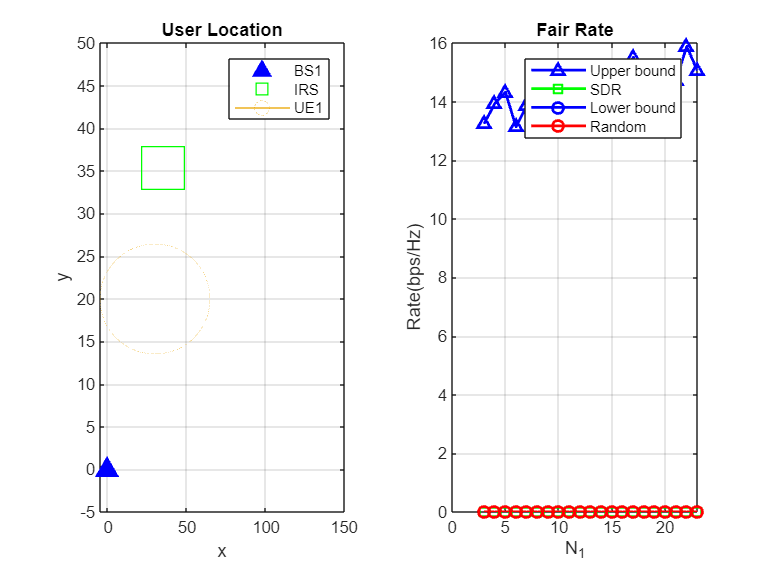


%% plot 1 SumRate
figure
tiledlayout(1 , 2)
nexttile
%  draw BS1
set(gca , 'FontName' , 'Times New Roman' , 'FontSize' , 11 , 'LineWidth' , 1.5)  ; 
plot(0 , 0 , '^' , 'MarkerSize' , 10 , ...
    'MarkerEdgeColor' , 'b' , ...
    'MarkerFaceColor' , 'b' , 'linewidth' , 1)
hold on
% draw IRS
plot(x_i , y_i , 'gs' , 'MarkerSize' , 30 , 'linewidth' , 1)
% draw BS1 users
plot(x0 , y0 , 'o-' , 'MarkerSize' , 60  *  R/10 , 'linewidth' , 0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150])  ; 
ylim([-5 50])  ; 
legend('BS1' , 'IRS' , 'UE1')  ; 
grid on
nexttile
% draw results
plot(start : step : start + (SV - 1) * step , final_Uband ,  'b-^' , 'linewidth' , 1.5)
hold on
plot(start : step : start + (SV - 1) * step , final_rate ,  'g-s' , 'linewidth' , 1.5)
plot(start : step : start + (SV - 1) * step , final_Lband ,  'b-o' , 'linewidth' , 1.5)
plot(start : step : start + (SV - 1) * step , random_final_rate ,  'r-o' , 'linewidth' , 1.5)
set(gcf , 'color' , 'w');
% ylim([0 16])
title('Fair Rate')
xlabel('N_1')
ylabel('Rate(bps/Hz)')
legend('Upper bound' ,'SDR' ,  'Lower bound' , 'Random')
grid on

## 2-user case

For SISO two user case we can calculate phase shift and power allocation in a closed form.

%%  
channel_gain = zeros(N1 , 1) ;
final_closed = zeros(SV  ,  1) ;
final_rate = zeros(SV , 1) ;
% random_final_rate = zeros(SV + 1 , 1) ;
tic
start = 8 ;
step = 2 ;
for N = start : step : start + (SV - 1) * step
    m = repmat('.' ,  1 ,  SV) ;
    i = (N - start)/step + 1 ;
    m(i) = '|' ;
    disp(m)
    for k = 1 : N_iter
        %% channel gains
        h_d = (10^0.2) * (randn(N1 , M_t , M_r) + 1j * randn(N1 , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x-x1).^2 + (y-y1).^2 + (z-z1).^2 )).^alpha_d) ;
        g = (10^0.2) * (randn(N , M_t , M_r) + 1j * randn(N , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x_i-x1).^2 + (y_i-y1).^2 + (z_i-z1).^2 )).^alpha_r) ;
        h_r = zeros(N , N1) ;
        for j = 1 : N1
            h_r( :  , j) = (10^0.2) * (randn(N , M_t , M_r) + 1j * randn(N , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x(j)-x_i).^2 + (y(j)-y_i).^2 + (z(j)-z_i).^2 )).^alpha_r) ;
        end
        [~ ,  Z_cvx1] = Rate2(h_d ,  g ,  h_r ,  N1 ,  N ,  P_T ,  noise_power ,  N_iter) ;
        Theta = diag(Z_cvx1) ;
        channel_gain = sort(abs(h_d + h_r'  *  Theta  *  g)).^2  *  P_T / noise_power ;
        [exact_rate ,  ~] = SISONoma(epsilon ,  channel_gain) ;
        final_rate(i) = final_rate(i) +  exact_rate ;
        [rate, Z_cvx] = Rate2(h_d ,  g ,  h_r ,  N1 ,  N ,  P_T ,  noise_power ,  N_iter) ;
        final_closed(i) = final_closed(i) +  rate ;
    end
end
%     %% without IRS
% for k = 1 : N_iter
%     [exact_rate ,  ~] = SISONoma(epsilon ,  sort(abs(h_d)).^2  *  P_T / noise_power) ;
%     final_rate(1) = final_rate(1) + exact_rate ;          
% end
final_rate = final_rate/N_iter ;
final_closed = final_closed/N_iter ;
toc

%% plot 1 SumRate
figure
tiledlayout(1 , 2)
nexttile
%  draw BS1
set(gca , 'FontName' , 'Times New Roman' , 'FontSize' , 11 , 'LineWidth' , 1.5)  ; 
plot(0 , 0 , '^' , 'MarkerSize' , 10 , ...
    'MarkerEdgeColor' , 'b' , ...
    'MarkerFaceColor' , 'b' , 'linewidth' , 1)
hold on
% draw IRS
plot(x_i , y_i , 'gs' , 'MarkerSize' , 30 , 'linewidth' , 1)
% draw BS1 users
plot(x0 , y0 , 'o-' , 'MarkerSize' , 60  *  R/10 , 'linewidth' , 0.5)
% plot(x0 , start + (SV-1) * step , 'o-' , 'MarkerSize' , 60  *  R/10 , 'linewidth' , 0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150])  ; 
ylim([-5 50])  ; 
legend('BS1' , 'IRS' , 'UE1')  ; 
grid on
nexttile
% draw results
plot(start : step : start + (SV - 1) * step , final_rate ,  'g-o' , 'linewidth' , 1.5)
hold on
plot(start : step : start + (SV - 1) * step , final_closed ,  'b-^' , 'linewidth' , 1.5)
% plot(start : step : start + (SV - 1) * step , random_final_rate ,  'r-o' , 'linewidth' , 1.5)
set(gcf , 'color' , 'w');
ylim([0 16])
title('Fair Rate(N_1=2)')
xlabel('N')
ylabel('Rate(bps/Hz)')
legend('SDR' ,  'Closed Form')
grid on